# 从文本文件中导入数据

用于从以下文本文件中导入数据的脚本:

由 MATLAB 于 2023-06-04 23:38:40 自动生成

## 设置导入选项并导入数据

opts = delimitedTextImportOptions("NumVariables", 3);

% 指定范围和分隔符
opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% 指定列名称和类型
opts.VariableNames = ["Var1", "VarName2", "VarName3"];
opts.SelectedVariableNames = ["VarName2", "VarName3"];
opts.VariableTypes = ["string", "double", "double"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% 指定变量属性
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");

% 导入数据
data63 = readmatrix("B:\360MoveData\Users\15711\Desktop\tempFile\数据分析\EX3\data6_3.txt", opts)

data63 =     52    30
    50    16
    47    23
    22    10
    16     8
    12    13
    47    19
    12    12
    36    10
    17    10


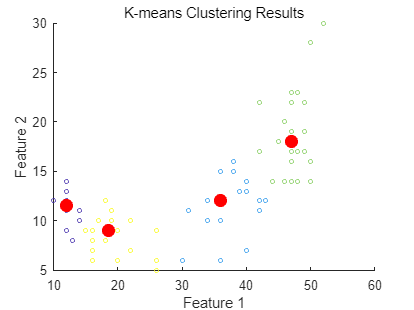

data = double(data63); 

% 使用 k-means 对数据进行聚类
k = 4; % 聚类数量
%[cluster_idx, cluster_center] = kmeans(data, k); %L2
[cluster_idx, cluster_center] = kmeans(data, k,'Distance', 'cityblock');%L1

% 可视化结果
figure;
scatter(data(:,1), data(:,2), 10, cluster_idx); % 将点颜色设置为聚类索引
hold on;
scatter(cluster_center(:,1), cluster_center(:,2), 100, 'r', 'filled'); % 将聚类中心用红色表示出来
title('K-means Clustering Results');
xlabel('Feature 1');
ylabel('Feature 2');

## 清除临时变量

clear opts